clear; close all; clc;

addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Motor\Potentio\Rightward\");

FileLength = 31;

DATA_R = cell(FileLength,1);
deg_VR = zeros(FileLength,1);

for k = 0 :FileLength-1
    FileName = sprintf("%.2f_data.out", k);
    DATA_R{k+1} = load(FileName);
    POTEN = DATA_R{k+1}(:, 4);
    deg_VR(k+1) = mean(POTEN);
end

deg_s = 120 / FileLength;
MAX = max(deg_VR)

MAX = 3.2524

MIN = min(deg_VR)

MIN = 1.5749

mean(deg_VR)

ans = 2.3679

(MAX+MIN)/2

ans = 2.4137


deg_R = -60+1:deg_s:60;

figure(1), grid on , hold on, box on, plot(deg_R, deg_VR, 'b', LineWidth = 2);
xlabel("Degree [Deg]");
ylabel("Potentiometer [V]");

% ================================= LEFT ====================================

FileLength = 28;
DATA_L = cell(FileLength, 1);
deg_VL = zeros(FileLength,1);

addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Motor\Potentio\");

for k = 1: FileLength
    FileName = sprintf("%.2f_data.out", k-1);
    DATA_L{k} = load(FileName);
    POTEN = DATA_L{k}(:,4);
    deg_VL(k) = mean(POTEN);
end

deg_s = 120 / FileLength;
MAX = max(deg_VL)

MAX = 3.2252

MIN = min(deg_VL)

MIN = 1.5427

mean(deg_VL)

ans = 2.4464

(MAX+MIN)/2

ans = 2.3840

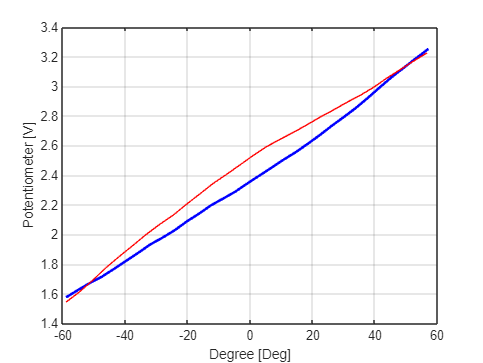


deg_L = -60+1:deg_s:60;
deg_L = flip(deg_L);

figure(1), plot(deg_L, deg_VL, 'r');